%该文件用来绘制影长随当日时间变化

n=n_days(2015,10,22);%根据自定义函数求得n
delte=abs((-23.45*sin(2*pi*(284+n)/365))/180)*2*pi;%delte为太阳赤纬
phi=((39+54/60+26/3600)/180)*2*pi;%由题，北京纬度为39度54分26秒

med_t=0.1;
t=9:med_t:15;%题求得是9点到15点
l=zeros(1,size(t,2));%用来存储所求的所有影长
for i=1:size(t,2) 
    st_t=t(1,i)-8+(116+23/60+29/3600)/15;%根据自定义函数转化为当地标准时间
    H=((15*(st_t-12))/180)*2*pi;%H为太阳时角
    alpha=asin(sin(delte)*sin(phi)+cos(delte)*cos(phi)*cos(H));%alpha为太阳光线的入射角度
    L=3;%表示直杆长度
    l(1,i)=abs(L/tan(alpha));%l表示此时影长
end
[lmax,indax]=max(l)

lmax =    7.230061872843377


indax =      1


[lmin,indin]=min(l)

lmin =    4.383628665972524


indin =     33


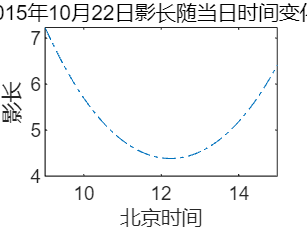

figure(1)
plot(t,l,'-.');
title('2015年10月22日影长随当日时间变化图');
xlabel('北京时间');
ylabel('影长');
xlim([9,15]);